clear
clc

% Given Variables and solved values for BDC and TDC ----------

% Initial conditions at BDC

Ti = 300;   % [K]
Pi = 1; % [atm]
Pi = Pi*101325; % [atm -> Pa]
Vi = 3.68E-4;   % [m^3]

% Given conditions

AF = 16;    % Air-fuel ratio
cr = 14;    % Compression ratio
phi = 1;    % Stoichoimetric condition

% Constants

Ru = 8314;  % [J/kg-K]
gamma = 1.4;

% Initial conditions at TDC

Vf = Vi/cr             % TDC Volume

Vf = 2.6286e-05

T0 = Ti*(cr^(gamma-1)) % Temp at TDC

T0 = 862.1294

P0 = Pi*(cr^gamma)     % Pressure at TDC

P0 = 4.0766e+06

 
% Xi of species

Ox0 = (AF/phi)/((AF/phi)+1) % AF/(AF+1)

Ox0 = 0.9412

F0 = 1-Ox0                  % Fuel mol fraction

F0 = 0.0588


% Initial molar concentrations of components 

Ox = Ox0*(P0/(Ru*T0))  % [kmol/m^3]

Ox = 0.5353

F = F0*(P0/(Ru*T0))    % [kmol/m^3]

F = 0.0335

Pr = 0                 % [kmol/m^3]

Pr = 0


y0 = [F,Ox,Pr,T0,P0];
tspan = [0 0.004];     % Main reaction occurs around 3 ms

% ODE Solver -------------------------------------------------

[t,y] = ode45(@PleaseWork, tspan, y0);

Fuel = y(:,1);
Oxygen = y(:,2);
Prod = y(:,3);
Temp = y(:,4);
Press = y(:,5);

%% Plots -----------------------------------------------------

% Concentrations

tiledlayout(3,1)
plot(t,Fuel,t,Oxygen,t,Prod)

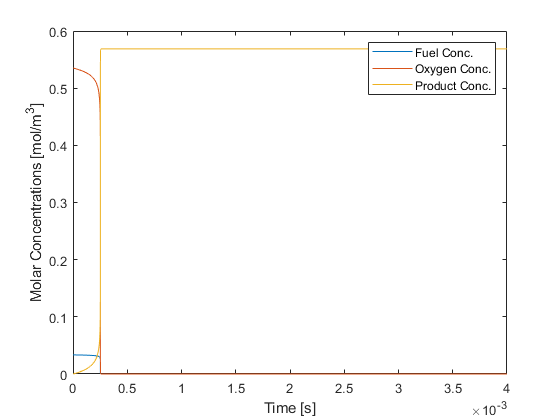

legend('Fuel Conc.','Oxygen Conc.','Product Conc.')
ylabel('Molar Concentrations [mol/m^3]')
xlabel('Time [s]')


% Temperature

plot(t,Temp)

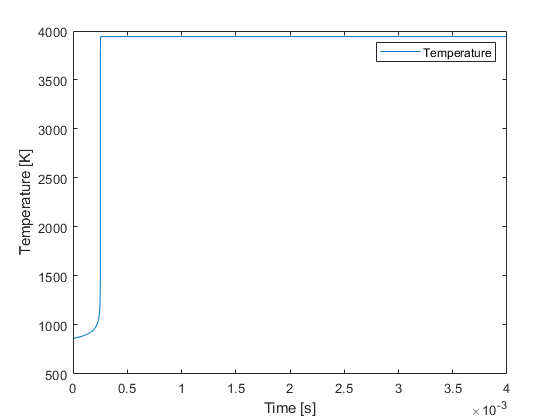

legend('Temperature')
ylabel('Temperature [K]')
xlabel('Time [s]')


% Pressures

plot(t,Press)

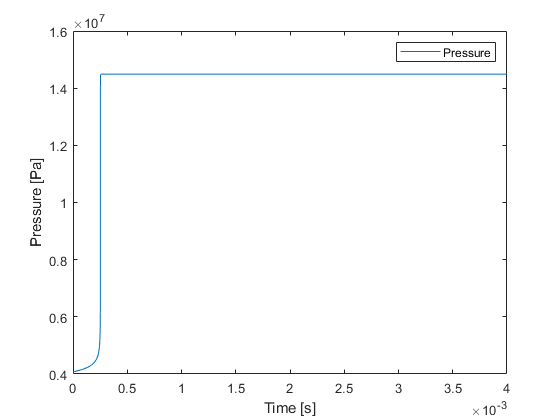

legend('Pressure')
ylabel('Pressure [Pa]')
xlabel('Time [s]')